该脚本实现了基于切比雪夫插值的FMM加速计算, 脚本的目标是输入一组二维点集坐标, 核函数A(x,y), 一个特征值迭代中间向量a, 输出一个向量u=Aa

References:The black-box fast multipole method;An Accelerated Kernel-Independent Fast Multipole Method in One Dimension

# **第一节:预计算**

% ==================== 定义参数 =================================
% 其他脚本输入:二维点集unique_coords, 点集的索引unicoord_indics
method=1; % 四叉树划分方式
max_points=80; % 盒子最多点数
min_points=60; % 盒子最少点数
eta = 0.1; % 分离系数,数字越大不可接受区域越广
use_parallel = 1; % 是否启用并行计算
cheb_num = 3;  % 设置一维方向节点数量
S = construct_Sab_chebfun_2D(cheb_num); % 映射函数句柄S(a,b),a是标准区间上的切比雪夫插值点, b是标准区间上的函数值点(比如GLL点)

% 核函数
l = 0.1; % 相关长度, 注意必须大于节点间距
sigma = 1; % 标准差
A =@(x, y) sigma^2 * exp(-norm(x - y)^2 / (l^2)); % 高斯平稳协方差,四维势函数
q_1 = ones(length(unicoord_indics),1)*10; % 特征值迭代中间向量


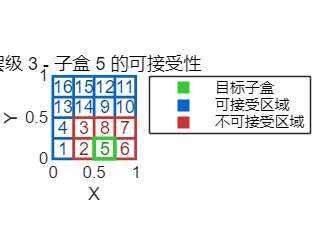

% 构建四叉树
tree_1 = quadtree_2D_decomposition(unique_coords, unicoord_indics, ...
    max_points, min_points,method);
% 输入：
    % unique_coords: 2D点集，[N×2]矩阵，每行是一个点的x,y坐标
    % unicoord_indics: 点集的索引集合，[N×1]向量，与unique_coords对应
    % max_points: 每个节点最大点数，控制划分深度
    % min_points:每个网格最小点数, 避免空网格
    % method: 划分方法，1为方法1（最小点数+空区域检查），2为方法2（动态中位数）
    % boundary规则:[左边界x,右边界x,下边界y,上边界y]
    % 输出：
    % tree: 四叉树结构，包含点坐标、索引、层级编号(level, number)和父盒索引(parent_level, parent_number)

% 可视化树结构
% quadtree_visualize_2D(tree_1);

% 可接受性判断于树结构重构
tree_2 = analyze_level_admissibility_2D0315(tree_1, eta,use_parallel);
% % 只获取admissibility_matrix, 可用于比较
% admissibility_matrix = generate_level_admissibility_matrices_2D(tree,eta); 


% 可视化可行性判断
visualize_admissibility_2D(tree_2, 3, 5,...
    'show_numbers', true);

% 输入：
    %   level_admissibility - analyze_level_admissibility_2D的输出结构
    %   target_level - 目标层级
    %   target_number - 目标子盒编号
    % 可选参数：
    %   'show_numbers' - 是否显示子盒编号 (true/false)
    %   'axis_limits' - 坐标轴范围 [xmin xmax ymin ymax]

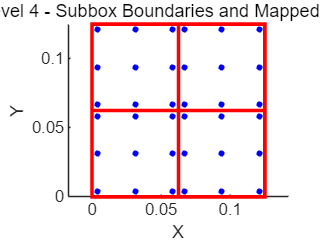

% 使用 chebpts 生成一维切比雪夫节点（第一类切比雪夫点,不包含端点）
cheb_p= chebpts(cheb_num,1); 

% 张量积生成二维网格节点
[X_c, Y_c] = meshgrid(cheb_p, cheb_p);

% 将节点转换为列向量形式, y优先
cheb_nodes =sortrows([X_c(:), Y_c(:)], [2, 1]);

% 将标准区间切比雪夫节点映射到物理单元的每一层的每个盒子上
tree_3 = map_to_box_elements_2D(cheb_nodes, tree_2, use_parallel);
n_levels = length(tree_3); % 总层数



% 可视化映射点集
visualize_level_2D(tree_3, n_levels-1);


% 将物理单元的每个盒子中的核函数点集映射到上一层的标准区间上
tree_4 = map_points_2D0314(tree_3, use_parallel);

% 计算每个盒子的转移矩阵和系数矩阵
% tree_5_each = compute_M2M_L2L_A_each_2D(S, A, cheb_nodes, tree_4, use_parallel);
% 
% % 直接计算整层的转移矩阵和系数矩阵
% tree_5_all = compute_M2M_L2L_A_ALL_2D(S, cheb_nodes, A, tree_4, use_parallel);

% % 将每个子盒的转移矩阵和系数矩阵聚合到一起(对角线拼接)
% tree_51 = assemble_layer_M2M_L2L_A_2D(tree_5, use_parallel);

% 同时计算整层和各个盒子的转移矩阵和系数矩阵
tree_5 = compute_M2M_L2L_A_2D0314(S, cheb_nodes, A, tree_4, use_parallel);

num_layers = length(tree_5); % 获取tree_5的层数
p_end = 1; % 初始化顶层索引
for i = 1:num_layers
    if nnz(tree_5(i).A_layer) > 0 % 检查A_layer是否非0（使用nnz判断非零元素个数）
        p_end = i-1; % 顶层
        break;
    end
end

# **第二节: FMM加速计算**

% 上行遍历计算输出矩,也即每一层每个代表点的权重,按盒子计算
% tree_6_each = compute_output_weights_2D0314_3(tree_5, q_1, p_end, use_parallel);

% 上行遍历计算输出矩,也即每一层每个代表点的权重,矩阵乘法计算
tree_6 = compute_output_weights_2D0314_4(tree_5, q_1, p_end, use_parallel);

% 从顶层向下计算每一层的输出向量 W_i
W = cell(num_layers, 1); % 使用cell数组存储每一层的W_i

for i = p_end:num_layers
    % 提取当前层的total_w_out向量和A_layer稀疏矩阵
    total_w_out = tree_6(i).total_m_out; % 输出向量
    A_layer = tree_6(i).A_layer;         % 稀疏矩阵
    
    % 计算 W_i = A_layer * total_w_out
    W{i} = A_layer * total_w_out;
end

% 从顶层向下计算 L_i
L = cell(num_layers, 1); % 使用cell数组存储每一层的L_i

% 顶层初始化：L_1 = W_1
L{p_end} = W{p_end};

% 从顶层向下逐层计算
for i = p_end+1:num_layers
    % 提取上一层的L2L_layer矩阵
    L2L_layer = tree_6(i-1).L2L_layer; % L2L矩阵用于层间传递
    
    % 计算当前层的 L_i = L2L_layer * L_{i-1} + W_i
    L{i} = L2L_layer * L{i-1} + W{i};
end

对于此运算，数组的大小不兼容。

相关文档


% 输出最终结果
L_end = L{num_layers}; % 最后一层的L_i即为L_end


f_far1 = tree_6(end).L2L_layer*L_end;% 远场贡献
f_near = compute_near_field_contribution_2D(tree_6, A, unique_coords, q_1, use_parallel);% 近场贡献
f_final = f_far1+f_near; %最终结果
test = R*q_1;
gg = mean(f_final-test)
relative_error = mean(abs(test - f_final) ./ abs(f_final))